## OFDM Parameters on 140 GHz

### The subcarrier spacing issue

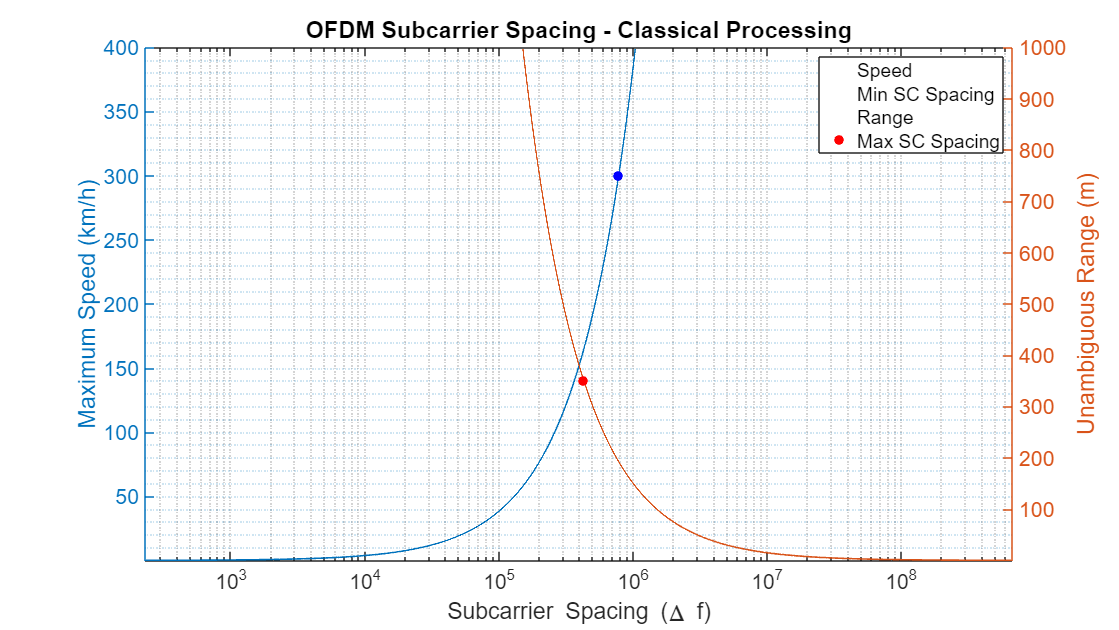

close all 
freqTx = 140e9; 
c = physconst('LightSpeed');
lambdaTx = c/freqTx;
NPointsNumSc = 4500;
maxVel = linspace(0,400, NPointsNumSc)./3.6; % m/s
UnambRange = linspace(0,1000, NPointsNumSc); 

%% CLASSIC PROCESSING
maxDopplerShift = 2*maxVel/lambdaTx;
minSubcarrierSpacing = 10*maxDopplerShift;
maxSubcarrierSpacing = c./(2*UnambRange);
minSubcarrierSpacingq = interp1(maxVel, minSubcarrierSpacing, 300/3.6);
maxSubcarrierSpacingq = interp1(UnambRange, maxSubcarrierSpacing, 350);

figureHandle = figure('Name', 'OFDM Subcarrier Spacing - Classical Processing', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);
yyaxis left;
semilogx(minSubcarrierSpacing, maxVel*3.6, 'LineWidth', 1.5, 'DisplayName',  'Speed'); 

axis tight; grid minor; fontsize(gca, 20, "points");
xlabel('Subcarrier Spacing (\Delta f)');
ylabel('Maximum Speed (km/h)');
hold on
plot(minSubcarrierSpacingq, 300, 'ob', 'DisplayName',  'Min SC Spacing', 'LineWidth', 3, 'MarkerFaceColor', 'b');
yyaxis right;
semilogx(maxSubcarrierSpacing, UnambRange, 'LineWidth', 1.5, 'DisplayName','Range'); 
ylabel('Unambiguous Range (m)');
plot(maxSubcarrierSpacingq, 350,'or', 'DisplayName', 'Max SC Spacing', 'LineWidth', 3,'MarkerFaceColor', 'r');
legend;
title('OFDM Subcarrier Spacing - Classical Processing');
hold off; 

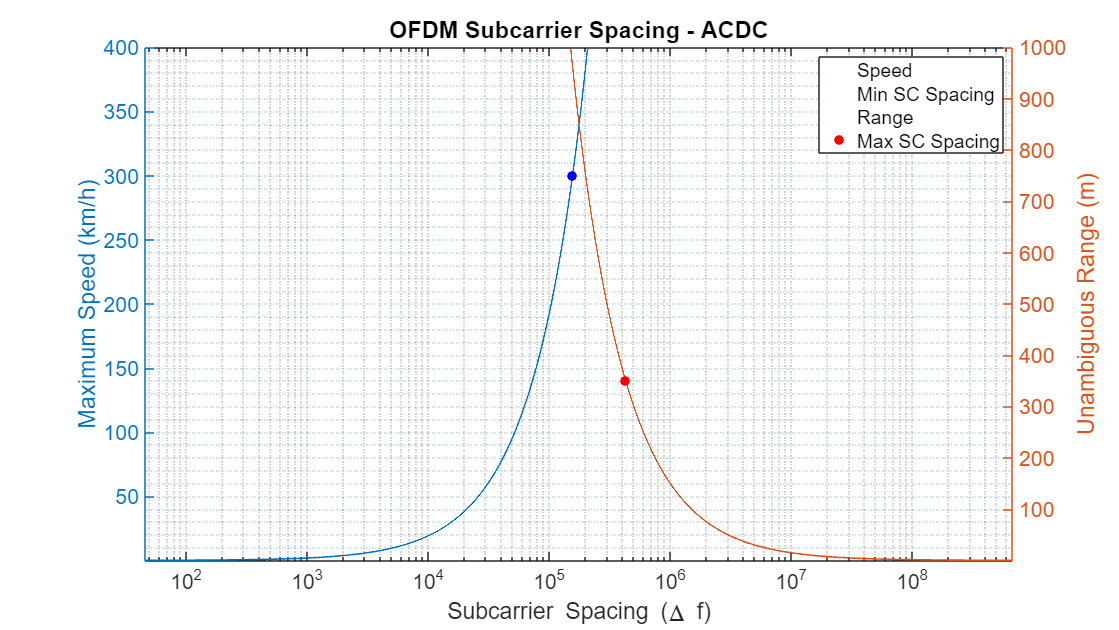

%% ACDC 
minSubcarrierSpacing = 2*maxDopplerShift; %% THE ONLY EFFECTIVE CHANGE 
minSubcarrierSpacingq = interp1(maxVel, minSubcarrierSpacing, 300/3.6);
maxSubcarrierSpacingq = interp1(UnambRange, maxSubcarrierSpacing, 350);

figureHandle2 = figure('Name', 'OFDM Subcarrier Spacing - ACDC', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);
yyaxis left;
semilogx(minSubcarrierSpacing, maxVel*3.6, 'LineWidth', 1.5, 'DisplayName',  'Speed'); 

axis tight; grid minor; fontsize(gca, 20, "points");
xlabel('Subcarrier Spacing (\Delta f)');
ylabel('Maximum Speed (km/h)');
hold on
plot(minSubcarrierSpacingq, 300, 'ob', 'DisplayName',  'Min SC Spacing', 'LineWidth', 3, 'MarkerFaceColor', 'b');
yyaxis right;
semilogx(maxSubcarrierSpacing, UnambRange, 'LineWidth', 1.5, 'DisplayName','Range'); 
ylabel('Unambiguous Range (m)');
plot(maxSubcarrierSpacingq, 350,'or', 'DisplayName', 'Max SC Spacing', 'LineWidth', 3,'MarkerFaceColor', 'r');
legend;
title('OFDM Subcarrier Spacing - ACDC');
hold off; 

### Setup and Requirements

clear

Definition of the requirements: Front Radar, for ex.: 

%% Front Radar 140 GHZ
requirements.maxRange = 350; 
requirements.uRange = requirements.maxRange; 
requirements.rangeRes = 1;
requirements.maxVel = 300/3.6; % We are considerating [-300, 300] km/h; 
requirements.velResolution = 0.3/3.6;
requirements.freqTx = 140e9;

Parameters = {'TX Frequency (GHz)'; 'Max Range(m)'; 'Range Resolution (m)'; 'Max Velocity (km/h)'; 'Velocity Resolution (km/h)' }; 
Values = [requirements.freqTx-9; requirements.maxRange; requirements.rangeRes; requirements.maxVel*3.6; requirements.velResolution*3.6]; 
LRR_requirements = table(Parameters, Values); 
disp(LRR_requirements)

              Parameters              Values 
    ______________________________    _______

    {'TX Frequency (GHz)'        }    1.4e+11
    {'Max Range(m)'              }        350
    {'Range Resolution (m)'      }          1
    {'Max Velocity (km/h)'       }        300
    {'Velocity Resolution (km/h)'}        0.3



### **Classical Processing **PARAMETRIZATION

The minimum subcarrier spacing should be much larger than the maximum doppler shift (in order to maintain orthogonality) 

lambdaTx = physconst('LightSpeed')/requirements.freqTx;
maxDopplerShift = 2*requirements.maxVel/lambdaTx

maxDopplerShift = 7.7832e+04

minSubcarrierSpacing = 10*maxDopplerShift

minSubcarrierSpacing = 7.7832e+05

The maximum SC spacing is determined by the max round trip (and max range): 

maxSubcarrierSpacing = physconst('LightSpeed')/(2*requirements.uRange)  

maxSubcarrierSpacing = 4.2827e+05

Taking the "maximum" (which is actually lower), and neglecting the orthogonality problems: 

scSpacing = maxSubcarrierSpacing

scSpacing = 4.2827e+05

BW, number of subcarriers and Range resolution: 

bw = rangeres2bw(requirements.rangeRes, physconst('LightSpeed'))

bw = 149896229

numSc = ceil(bw/scSpacing)

numSc = 350

% Power of 2 (and increase, so we keep the range requirement, but loose even more orthogonality, if we adjust the scSpacing)
% The other option is increase the bandwidth, reducing the range resolution
% but requesting more from the DAC 
numSc = 2^(nextpow2(numSc))   

numSc = 512

If CP-OFDM: 

T = 1/scSpacing % OFDM Symbol Period 

T = 2.3349e-06

SRI = lambdaTx/(4*requirements.maxVel)

SRI = 6.4241e-06

tCp = 2*requirements.maxRange/physconst('LightSpeed')

tCp = 2.3349e-06

tCp+T % Since lower than SRI, we can add a dwell time or reduce the SRI to increase max vel

ans = 4.6699e-06

If RS-OFDM, which means no cyclic prefix and no dwell time: 

% T = 1/scSpacing % OFDM Symbol Period 
% dt = T/(numSc); % Sample period
% tOFDM = T;
% SRI = tOFDM;

Maximum unambiguous velocity range (here, we are neglecting again the lost on orthogonality)  

effMaxVel_Range = lambdaTx/(2*SRI)

effMaxVel_Range = 166.6667

numSymbols = effMaxVel_Range/requirements.velResolution

numSymbols = 2000

numSymbols = 2^(nextpow2(numSymbols))      % Power of 2

numSymbols = 2048

### ACDC PARAMETRIZATION

clc
lambdaTx = physconst('LightSpeed')/requirements.freqTx;
maxDopplerShift = 2*requirements.maxVel/lambdaTx

maxDopplerShift = 7.7832e+04

minSubcarrierSpacing = 2*maxDopplerShift

minSubcarrierSpacing = 1.5566e+05

The maximum SC spacing is determined by the max round trip (and max range): 

maxSubcarrierSpacing = physconst('LightSpeed')/(2*requirements.uRange)  

maxSubcarrierSpacing = 4.2827e+05

Taking the "minimum" (to maximize T and improve energy efficiency): 

scSpacing = minSubcarrierSpacing

scSpacing = 1.5566e+05

BW, number of subcarriers and Range resolution: 

bw = rangeres2bw(requirements.rangeRes, physconst('LightSpeed'))

bw = 149896229

numSc = ceil(bw/scSpacing)

numSc = 963

numSc = 2^(nextpow2(numSc))  % Power of 2 (need further adjustements of either scSpacing or BW)

numSc = 1024

If RS-OFDM (then we are able to perform ACDC): 

T = 1/scSpacing % OFDM Symbol Period 

T = 6.4241e-06

dt = T/(numSc); % Sample period
tOFDM = T; % Usually T + Tcp (Tcp = 0s on RS-OFDM)
SRI = tOFDM; % Usually tOFDM + Dwell Time (Dwell Time = 0s on RS-OFDM)

Observe that it's impossible, because the period of the OFDM sym + cyclic prefix is larger than the 

Maximum unambiguous velocity range 

effMaxVel_Range = lambdaTx/(2*SRI) 

effMaxVel_Range = 166.6667

numSymbols = effMaxVel_Range/requirements.velResolution

numSymbols = 2000

numSymbols = 2^(nextpow2(numSymbols))      % Power of 2

numSymbols = 2048